# DEMO for Corrosion Fatigue Simulation using 3-stage model

Simulation with random sampled stress ranges

clear; close all; clc; format compact; format long;
cd 'E:\CYW\Matlab\CF';      % Path of Codes
addpath(genpath(pwd));
set(0,'defaultfigurecolor','w');

## 0. Stress range sampling from stress spectra

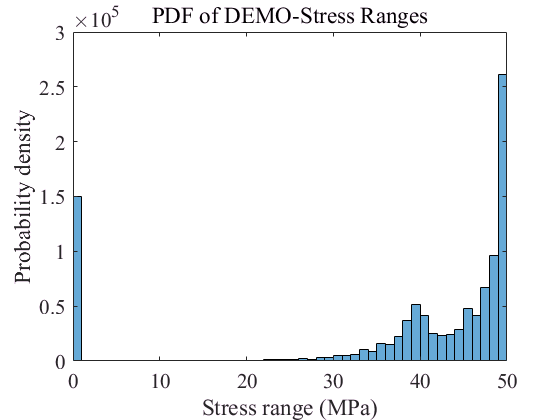

dStrAR = load('dStrEqv[DEMO_CF]');                   % Array Storing for Stress ranges
dStrAR = dStrAR.dStrE;

histogram(dStrAR,50);                               % Plot the histogram of Stress Ranges
set(gca,'fontname','Times New Roman','fontsize',16,'LineWidth',0.2);
xlabel('Stress range (MPa)','fontsize',16,'fontname','Times New Roman');
ylabel('Probability density','fontsize',16,'fontname','Times New Roman');
title('PDF of DEMO-Stress Ranges');

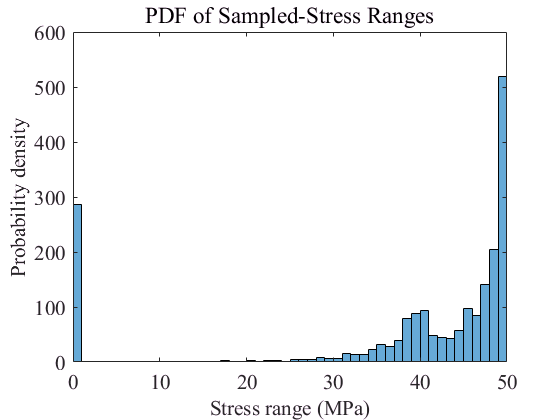


num_sam = 2000;                                         % number of samples
dStr_sam = dStrAR(randperm(length(dStrAR),num_sam)');   % Sampling
histogram(dStr_sam,50);                                 % Plot the histogram of Sampled Stress Ranges
set(gca,'fontname','Times New Roman','fontsize',16,'LineWidth',0.2);
xlabel('Stress range (MPa)','fontsize',16,'fontname','Times New Roman');
ylabel('Probability density','fontsize',16,'fontname','Times New Roman');
title('PDF of Sampled-Stress Ranges');

## 1. Stage 1 - Effective Crack Initiation under Corrosion & Fatigue (summation)

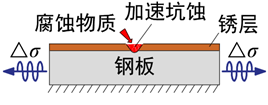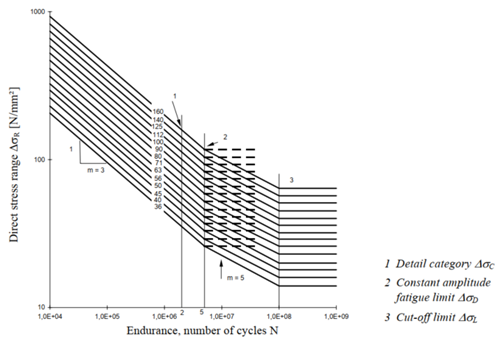


$$
\left( \frac{dD}{dt} \right)_{CF1} = \frac{{dD}_{cor}}{dt} + \frac{{dD}_{fat}}{dt} = \frac{1}{dt} \bullet \left( \frac{a}{a_{i}} \right)_{cor} + \frac{1}{dt}\left( {\sum_{i}\left. \frac{N_{i}}{\left\lbrack N_{i} \right\rbrack} \right)} \right._{fat}$$


D = Damage Factor (0.3 for initiation); t = time; cor/fat = corrosion/fatigue

a = equivalent (corrosion pit) crack depth; ai = effective depth after crack initiation; 

[Ni] = crack initiation life allowance for stress block dσi; Ni cycles by dσi

Dfat = damage solved from fatigue; Dcor = damage sovled from corrosion


$$D_{fat} = {\sum_{i}{\left( \frac{{\mathrm{\Delta}\sigma}_{i}}{{\mathrm{\Delta}\sigma}_{C,D,L}} \right)^{m_{1,2,3}} \times \frac{n_{i}}{N_{C,D,L}}}}$$


$a_{cor} = Q \times t^{1/3}$, Q = 0.19 for C4 (Qingdao) for **t in years**

**Effective initial crack size to mark transition between stages 1 and 2**

$
\frac{da_{i}}{dN} = C \bullet \left( {\mathrm{\Delta}K\left( a_{i} \right) - {\mathrm{\Delta}K}_{th}} \right)^{m} = \frac{a_{i}}{N_{i}}$，in which $\mathrm{\Delta}K\left( a_{i} \right) = Y\left( a_{i} \right)\sqrt{\pi a_{i}}\mathrm{\Delta}\sigma$

f_load = 1369/24/60/60;                         % loading frequency (HZ: 1/s)
Q_cor = 0.19;                                   % pit corrosion factor (t in years)
D_int = 0.3;                                    % damage limit for crack initiation under fatigue

y2s = 365*24*60*60;                             % year-to-seconds
a_fail = 16;                                    % size of fatigue failure (mm)
L=13;                                           %焊缝长度(mm)
B=16;                                           %板厚度(mm)

m1 = 3; m2 = 5; m3 = 22;                        % Power index for Stage 1,2,3
FATc = 100;                                     % FAT 100 for Rib-to-deck Joint
FATd = (2/5)^(1/m1) * FATc;                     % FAT at 5 million
FATt = (5/100)^(1/m2) * FATd;                   % FAT Threshold at 100 Million
C_fcg = 5.21e-13;                               % FCG rate in air
cor_fcg = 1+(Q_cor/0.19)*0.5;                   % FCG rate improvement by corrosion (1.5 for C4)
m_fcg = 3;                                      % Power index
dKth = 63;                                      % Fatigue threshold: N/mm^(3/2)

StrR = 0;                                       % Stress Ratio

dStrAR_D1 = sum((dStrAR(dStrAR>FATd)./FATd).^m1)/5e6...
    + sum((dStrAR(dStrAR<=FATd & dStrAR>FATt)./FATd).^m2)/5e6...
    + sum((dStrAR(dStrAR<FATt)./FATt).^m3)/100e6;               % Total Equivalent Damge by Spectra
dStrAR_Neff = length(dStrAR)/dStrAR_D1;                         % Equivalent Life Allowance for the Spectra
dStrEqv = (dStrAR_Neff<5e6)*((5e6/dStrAR_Neff).^(1/m1).*FATd)...
    + (dStrAR_Neff>5e6 & dStrAR_Neff<100e6)*(5e6/dStrAR_Neff).^(1/m2).*FATd...
    + (dStrAR_Neff>100e6)*(100e6/dStrAR_Neff).^(1/m3).*FATt;    % Equivalent Stress Range
fprintf("Damage Equivalent Stress Range for the spectra = %6.2f\n",dStrEqv);

Damage Equivalent Stress Range for the spectra =  43.94



D_sam = sum((dStr_sam(dStr_sam>FATc)/FATc).^m1./2e6);
D_sam = D_sam + sum((dStr_sam(dStr_sam>FATt & dStr_sam<=FATd)/FATd).^m2./5e6);
D_sam = D_sam + sum((dStr_sam(dStr_sam<=FATt)/FATt).^m3./100e6);
dDfa_2_dN = D_sam/num_sam;                      % Equivalent fatigue damage per cycle
dDfa_2_dt = f_load.*dDfa_2_dN*y2s;              % Equivalent fatigue damage per year


N_eff = 1/dDfa_2_dN;                            % effetive initiation cycles (FAT)
if N_eff < 2e6
    dStr_eqv = (2e6/(N_eff)*FATc.^m1).^(1/m1);
elseif N_eff >= 5e6 && N_eff < 100e6
    dStr_eqv = (5e6/N_eff*FATd.^m2).^(1/m2);
elseif N_eff > 100e6
    dStr_eqv = (100e6/N_eff*FATt.^m3).^(1/m3);
end
fprintf("Damage Equivalent Stress Range for the samples = %6.2f\n",dStr_eqv);

Damage Equivalent Stress Range for the samples =  44.03



N_int = D_int/dDfa_2_dN;                        % crack initiation cycles (FAT)
Y_fcg = 1.20;                                   % correction factor for FCG

a_int = (dKth/FATt/Y_fcg)^2/pi;                 % direct solution using EIFS

dmg_t = @(t) dDfa_2_dt.*t./D_int + Q_cor.*(t).^(1/3)/a_int - 1;
t_int = fsolve(dmg_t,0.1);                      % crack initiation life (in years)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



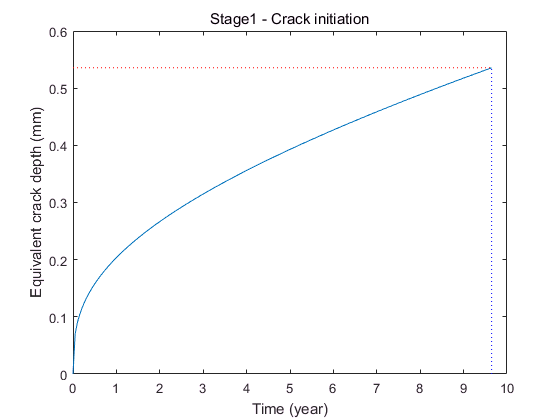


t_his = (0:0.05:floor(t_int))';                 % History of time steps
t_his = unique([t_his;t_int]);
a_his = (dmg_t(t_his)+1).*a_int;                % History of crack depth (estimated by damage)
c_his = a_his./0.62;
CGR_fat = ones(size(t_his)).*dDfa_2_dt;         % History of crack growth rate under fatigue
CGR_cor = Q_cor.*t_his.^(-2/3)/3;               % History of crack growth rate under corrosion

plot(t_his,a_his); hold on;
plot([0,t_int],[a_int,a_int],'r:');
plot([t_int,t_int],[0,a_int],'b:');
hold off;
xlabel("Time (year)"); ylabel("Equivalent crack depth (mm)");
title('Stage1 - Crack initiation');

fprintf('crack initiation costs %8.2f years\n',t_int);

crack initiation costs     9.65 years


## 2. Stage 2 - Corrosion Fatigue Competition

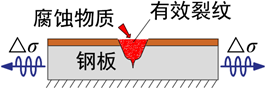


$$\left( \frac{dD}{dt} \right)_{CF2} = max\left\{ \left( \frac{da}{dt} \right)_{cor},\left( {f \bullet \frac{da}{dN}} \right)_{fat} \right\}$$



$$\left( \frac{da}{dt} \right)_{cor} = \frac{d\left( Q \bullet t^{1/3} \right)}{dt} = \frac{1}{3}Q \bullet t^{- 2/3}$$



$$\left( {f \bullet \frac{da}{dN}} \right)_{fat} = f \bullet C \bullet \left( {\mathrm{\Delta}K\left( a_{t} \right) - {\mathrm{\Delta}K}_{th}} \right)^{m}$$


**计算应力强度因子：**

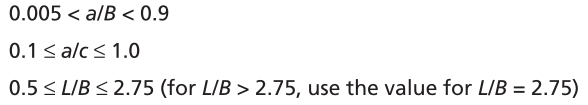

**深度方向：**

**当a/B>0.5时，取Mkba>=Y_fcg**

**当a/c<0.1时，取a/c=0.1**

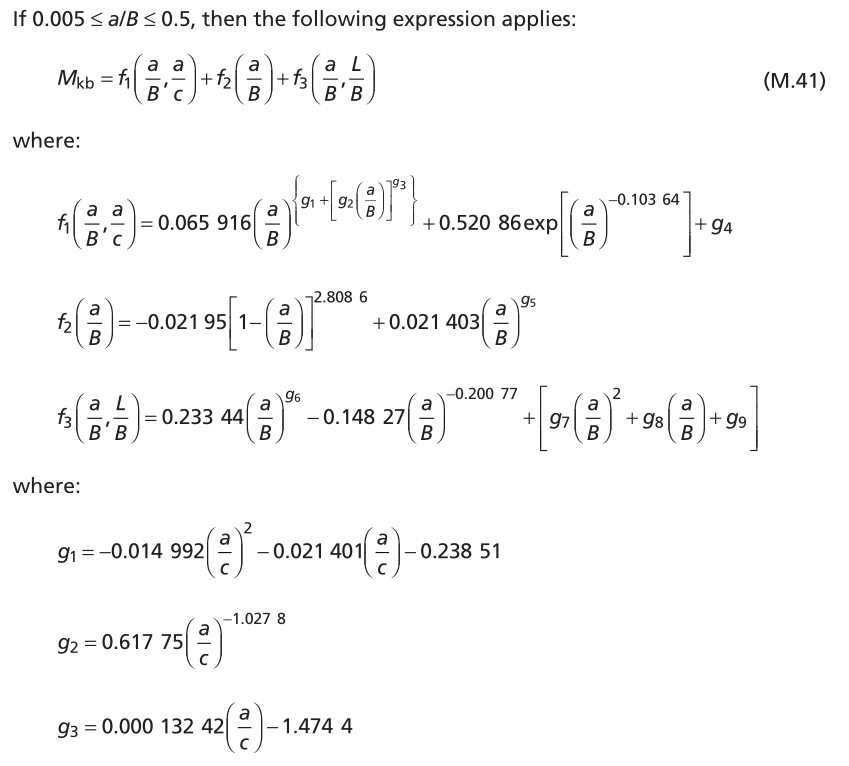

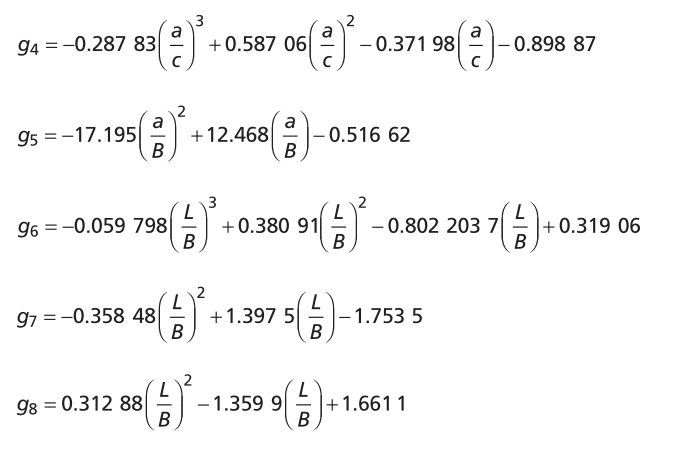

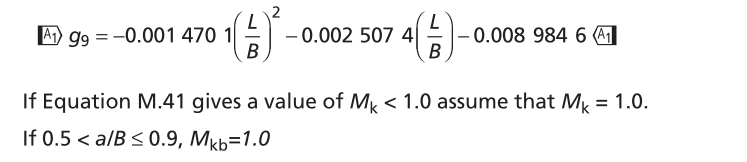

**表面方向：**

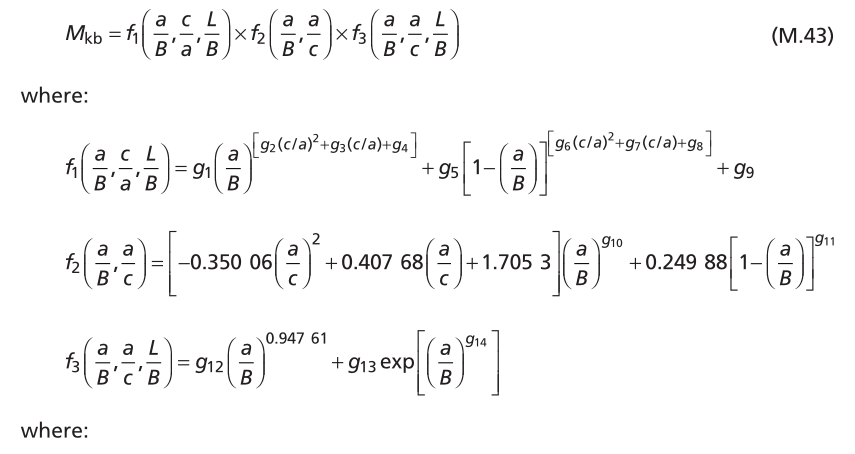

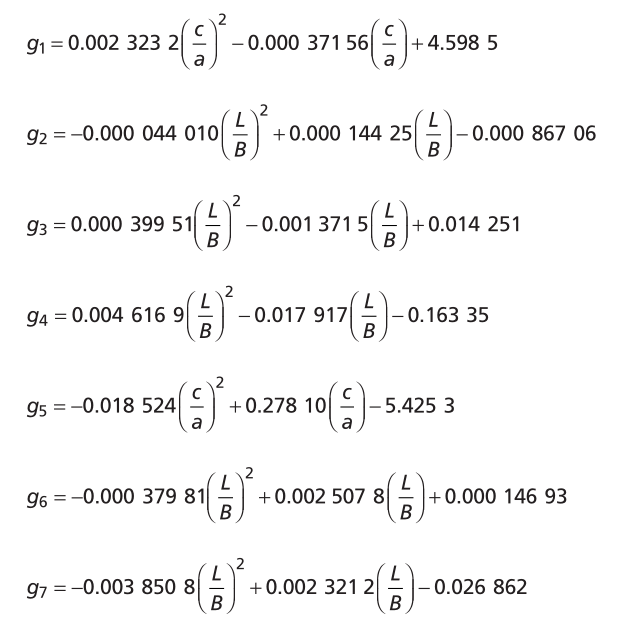

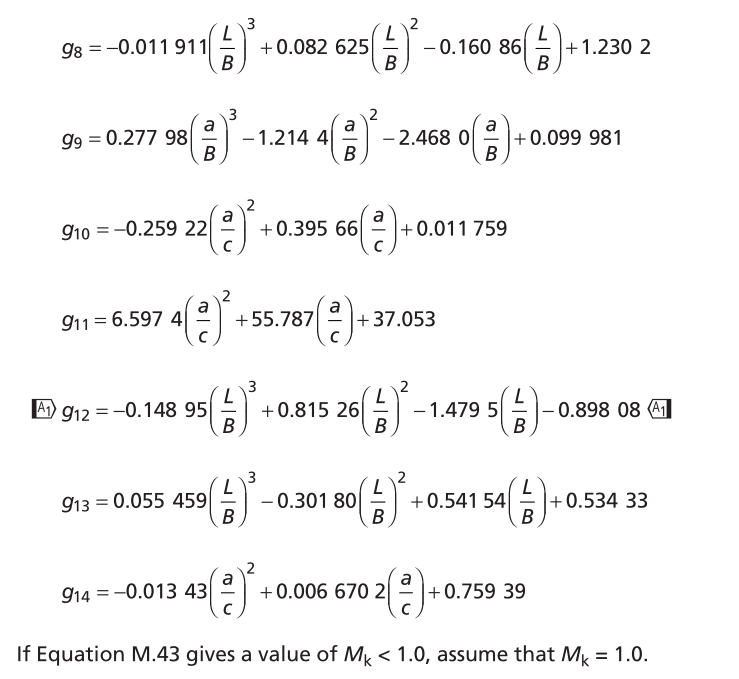

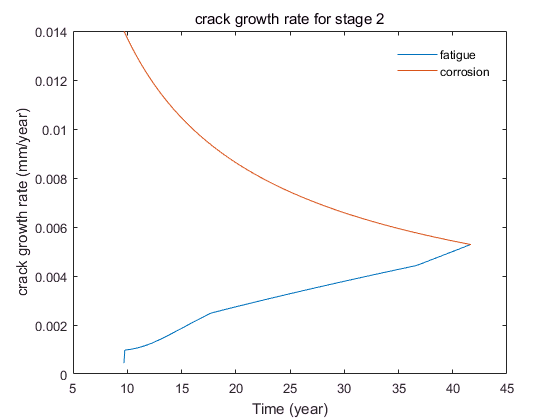

da_lim = 1e-3;                                  % limit for crack size update
t_cur = t_int;                                  % current time for stage 2 (years)
a_t = a_int;                                    % start (initial) crack size
c_int = a_int/0.62;
c_t = c_int;

dKa_t = Y_fcg*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges
da2dt_fat = sum(C_fcg*cor_fcg*((dKa_t(dKa_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
CGR_fat=[CGR_fat;da2dt_fat];
CGR_fatc=CGR_fat/0.62;
% da/dt under fatigue using sampled stress ranges (in year)
da2dt_cor = Q_cor*t_cur.^(-2/3)/3;              % da/dt under corrosion (in year)
CGR_cor =[CGR_cor;da2dt_cor];
          
    dt = da_lim./da2dt_cor;
    t_cur = t_cur + dt;
    t_his = [t_his;t_cur];
    a_t = a_t + da_lim;
    a_his = [a_his;a_t];
    c_t = c_t + da_lim./0.62;
    c_his = [c_his;c_t];

    Mkba_his = 0;
    Mkbc_his = 0;
    fc1_his = 0;
    fc2_his = 0;
    fc3_his = 0;
    gc1_his = 0;
    gc2_his = 0;
    gc3_his = 0;
    gc4_his = 0;
    gc5_his = 0;
    gc6_his = 0;
    gc7_his = 0;
    gc8_his = 0;
    gc9_his = 0;
    

while da2dt_fat < da2dt_cor
 
    %计算深度方向上的应力强度因子
    
    
    %0.1<a/c<10;判断a/c的大小
    if c_t > 10*a_t
        c_a = 10;
        a_c = 0.1;
    else
        c_a = c_t/a_t;
        a_c = a_t/c_t;
    end
    
    
    if a_t/a_fail<0.5
    %计算f1
        ga1 = -0.014992 * (a_c)^ 2 - 0.021401 * (a_c) - 0.23851;
        ga2 = 0.61775 * (a_c)^(-1.0278);
        ga3 = 0.00013242 * (a_c) - 1.4744;
        ga4 = -0.28783 * (a_c)^ 3 + 0.58706 * (a_c)^ 2- 0.37198 * (a_c) - 0.89887;
        fa1 = 0.065916 * (a_t / B)^(ga1 + (ga2 * (a_t / B))^ ga3)+ 0.52086 * exp((a_t / B)^ (-0.10364)) + ga4;
        %计算f2
        ga5 = -17.195 * (a_t / B)^ 2+ 12.468 * (a_t / B) - 0.51662;
        fa2 = -0.02195 * (1 - (a_t / B))^ 2.8086 + 0.021403 *(a_t / B)^ ga5;
        %计算f3
        ga6 = -0.059798 * (L / B)^ 3 + 0.38091 * (L / B)^ 2.0 - 0.8022037 * (L / B) + 0.31906;
        ga7 = -0.35848 * (L / B)^ 2 + 1.3975 * (L / B) - 1.7535;
        ga8 = 0.31288 * (L / B)^ 2 - 1.3599 * (L / B) + 1.6611;
        ga9 = -0.0014701 * (L / B)^ 2 - 0.0025074 * (L / B) - 0.0089846;
        fa3 = 0.23344 * (a_t / B)^ ga6 - 0.14827 * (a_t / B)^ (-0.20077) + ga7 * (a_t / B)^ 2 + ga8 * (a_t / B) + ga9;
        %计算Mkba
        Mkba = fa1 + fa2 + fa3;
        if Mkba < Y_fcg
            Mkba = Y_fcg;
        end
    else
        Mkba = Y_fcg;
    end
    
    Mkba_his = [Mkba_his;Mkba];
        
    
    %计算c方向上的应力强度因子
    
    gc1 = 0.0023232 * (c_a)^2 - 0.00037156*(c_a) + 4.5985;
    gc2 = -0.000044010 * (L/B)^2 + 0.00014425 * (L/B) - 0.00086706;
    gc3 = 0.00039951*(L/B)^2 - 0.0013715*(L/B) + 0.014251;
    gc4 = 0.0046169*(L/B)^2 - 0.017917*(L/B) - 0.16335;
    gc5 = -0.018524*(c_a)^2 + 0.27810*(c_a) -5.4253;
    gc6 = -0.00037981*(L/B)^2 + 0.0025078*(L/B) + 0.00014693;
    gc7 = -0.0038508*(L/B)^2 + 0.0023212*(L/B) -0.026862;
    gc8 = -0.011911*(L/B)^3 + 0.082625*(L/B)^2 - 0.16086*(L/B) +1.2302;
    gc9 = 0.27798*(a_t/B)^3 - 1.2144*(a_t/B)^2 - 2.4680*(a_t/B) + 0.099981;
    %计算f1
    fc1 = gc1*(a_t/B)^(gc2*(c_a)^2 + gc3*(c_a) + gc4) + gc5*(1-(a_t/B))^(gc6*(c_a)^2 + gc7*(c_a) + gc8) + gc9;
 
    gc10 = -0.25922*(a_c)^2 + 0.39566*(a_c) + 0.011759;
    gc11 = 6.5974*(a_c)^2 + 55.787*(a_c) + 37.053;
    
    %计算f2
    fc2 = (-0.35006*(a_c)^2 + 0.40768*(a_c) + 1.7053)*(a_t/B)^gc10 + 0.24988*(1-(a_t/B))^gc11;
    
    gc12 = -0.14895*(L/B)^3 + 0.81526*(L/B)^2 - 1.4795*(L/B) - 0.89808;
    gc13 = 0.055459*(L/B)^3 - 0.30180*(L/B)^2 + 0.54154*(L/B) + 0.53433;
    gc14 = -0.01343*(a_c)^2 + 0.0066702*(a_c) + 0.75939;
    %计算f3
    fc3 = gc12*(a_t/B)^0.94761 + gc13*exp((a_t/B)^gc14);
    
    %计算Mkbc
    Mkbc = fc1 * fc2 * fc3;
    
    Mkbc_his = [Mkbc_his;Mkbc];
    fc1_his = [fc1_his;fc1];
    fc2_his = [fc2_his;fc2];
    fc3_his = [fc3_his;fc3];
    gc1_his = [gc1_his;gc1];
    gc2_his = [gc2_his;gc2];
    gc3_his = [gc3_his;gc3];
    gc4_his = [gc4_his;gc4];
    gc5_his = [gc5_his;gc5];
    gc6_his = [gc6_his;gc6];
    gc7_his = [gc7_his;gc7];
    gc8_his = [gc8_his;gc8];
    gc9_his = [gc9_his;gc9];
    
    
    
    
    
    
    dKa_t = Mkba*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges; a 方向
    dKc_t = Mkbc*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges; c 方向
    %a方向上的疲劳扩展速率
    da2dt_fat = sum(C_fcg*cor_fcg*((dKa_t(dKa_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
    %c方向上的疲劳扩展速率
    dc2dt_fat = sum(C_fcg*cor_fcg*((dKc_t(dKc_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
    CGR_fat = [CGR_fat;da2dt_fat];
    CGR_fatc = [CGR_fatc;dc2dt_fat];
    % da/dt under fatigue using sampled stress ranges (in year)
    da2dt_cor = Q_cor*t_cur.^(-2/3)/3;              % da/dt under corrosion (in year)
    CGR_cor = [CGR_cor;da2dt_cor];
    
    
    
            
    dt = da_lim./da2dt_cor;
    t_cur = t_cur + dt;
    t_his = [t_his;t_cur];
    a_t = a_t + da_lim;
    a_his = [a_his;a_t];
    c_t = c_t + dt*dc2dt_fat;
    c_his = [c_his;c_t];
    
    
    
    if a_t > a_fail
        break;
    end
end

t_compe = t_cur;                                    % Ending time for stage 2 (in year)
plot(t_his(t_his>t_int),CGR_fat(t_his>t_int),t_his(t_his>t_int),CGR_cor(t_his>t_int));
xlabel("Time (year)"); ylabel("crack growth rate (mm/year)");
title('crack growth rate for stage 2');
legend({'fatigue','corrosion'},"Box","off");

fprintf('corrosion-fatigue competition costs %8.2f years\n',t_compe - t_int);

corrosion-fatigue competition costs    32.04 years


## 3. Stage 3 - Corrosion-assisted Fatigue

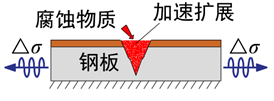


$$\left( \frac{dD}{dt} \right)_{CF2} = \left( \frac{da}{f \bullet dN} \right)_{fat} = \frac{1}{f}C \bullet \left( {\mathrm{\Delta}K\left( a_{t} \right) - {\mathrm{\Delta}K}_{th}} \right)^{m}$$


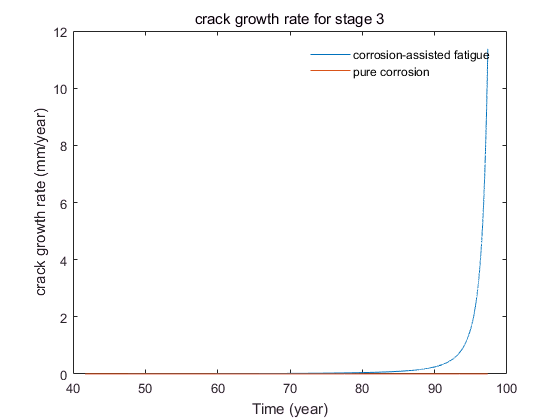


while a_t < a_fail
    
    %计算深度方向上的应力强度因子
    
    %0.1<a/c<10;判断a/c的大小
    if c_t > 10*a_t
        c_a = 10;
        a_c = 0.1;
    else
        c_a = c_t/a_t;
        a_c = a_t/c_t;
    end
    
    
    if a_t/a_fail<0.5
    %计算f1
        ga1 = -0.014992 * (a_c)^ 2 - 0.021401 * (a_c) - 0.23851;
        ga2 = 0.61775 * (a_c)^(-1.0278);
        ga3 = 0.00013242 * (a_c) - 1.4744;
        ga4 = -0.28783 * (a_c)^ 3 + 0.58706 * (a_c)^ 2- 0.37198 * (a_c) - 0.89887;
        fa1 = 0.065916 * (a_t / B)^(ga1 + (ga2 * (a_t / B))^ ga3)+ 0.52086 * exp((a_t / B)^ (-0.10364)) + ga4;
        %计算f2
        ga5 = -17.195 * (a_t / B)^ 2+ 12.468 * (a_t / B) - 0.51662;
        fa2 = -0.02195 * (1 - (a_t / B))^ 2.8086 + 0.021403 *(a_t / B)^ ga5;
        %计算f3
        ga6 = -0.059798 * (L / B)^ 3 + 0.38091 * (L / B)^ 2.0 - 0.8022037 * (L / B) + 0.31906;
        ga7 = -0.35848 * (L / B)^ 2 + 1.3975 * (L / B) - 1.7535;
        ga8 = 0.31288 * (L / B)^ 2 - 1.3599 * (L / B) + 1.6611;
        ga9 = -0.0014701 * (L / B)^ 2 - 0.0025074 * (L / B) - 0.0089846;
        fa3 = 0.23344 * (a_t / B)^ ga6 - 0.14827 * (a_t / B)^ (-0.20077) + ga7 * (a_t / B)^ 2 + ga8 * (a_t / B) + ga9;
        %计算Mkba
        Mkba = fa1 + fa2 + fa3;
        if Mkba < Y_fcg
            Mkba = Y_fcg;
        end
    else
        Mkba = Y_fcg;
    end
    
    Mkba_his = [Mkba_his;Mkba];
        
    
    %计算c方向上的应力强度因子
    
    gc1 = 0.0023232 * (c_a)^2 - 0.00037156*(c_a) + 4.5985;
    gc2 = -0.000044010 * (L/B)^2 + 0.00014425 * (L/B) - 0.00086706;
    gc3 = 0.00039951*(L/B)^2 - 0.0013715*(L/B) + 0.014251;
    gc4 = 0.0046169*(L/B)^2 - 0.017917*(L/B) - 0.16335;
    gc5 = -0.018524*(c_a)^2 + 0.27810*(c_a) -5.4253;
    gc6 = -0.00037981*(L/B)^2 + 0.0025078*(L/B) + 0.00014693;
    gc7 = -0.0038508*(L/B)^2 + 0.0023212*(L/B) -0.026862;
    gc8 = -0.011911*(L/B)^3 + 0.082625*(L/B)^2 - 0.16086*(L/B) +1.2302;
    gc9 = 0.27798*(a_t/B)^3 - 1.2144*(a_t/B)^2 - 2.4680*(a_t/B) + 0.099981;
    %计算f1
    fc1 = gc1*(a_t/B)^(gc2*(c_a)^2 + gc3*(c_a) + gc4) + gc5*(1-(a_t/B))^(gc6*(c_a)^2 + gc7*(c_a) + gc8) + gc9;
 
    gc10 = -0.25922*(a_c)^2 + 0.39566*(a_c) + 0.011759;
    gc11 = 6.5974*(a_c)^2 + 55.787*(a_c) + 37.053;
    
    %计算f2
    fc2 = (-0.35006*(a_c)^2 + 0.40768*(a_c) + 1.7053)*(a_t/B)^gc10 + 0.24988*(1-(a_t/B))^gc11;
    
    gc12 = -0.14895*(L/B)^3 + 0.81526*(L/B)^2 - 1.4795*(L/B) - 0.89808;
    gc13 = 0.055459*(L/B)^3 - 0.30180*(L/B)^2 + 0.54154*(L/B) + 0.53433;
    gc14 = -0.01343*(a_c)^2 + 0.0066702*(a_c) + 0.75939;
    %计算f3
    fc3 = gc12*(a_t/B)^0.94761 + gc13*exp((a_t/B)^gc14);
    
    %计算Mkbc
    Mkbc = fc1 * fc2 * fc3;
    
    Mkbc_his = [Mkbc_his;Mkbc];

    dKa_t = Mkba*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges; a 方向
    dKc_t = Mkbc*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges; c 方向
    %a方向上的疲劳扩展速率
    da2dt_fat = sum(C_fcg*cor_fcg*((dKa_t(dKa_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
    %c方向上的疲劳扩展速率
    dc2dt_fat = sum(C_fcg*cor_fcg*((dKc_t(dKc_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
    CGR_fat = [CGR_fat;da2dt_fat];
    CGR_fatc = [CGR_fatc;dc2dt_fat];
    % da/dt under fatigue using sampled stress ranges (in year)
    da2dt_cor = Q_cor*t_cur.^(-2/3)/3;              % da/dt under corrosion (in year)
    CGR_cor = [CGR_cor;da2dt_cor];
    
    
    
            
    dt = da_lim./da2dt_fat;
    t_cur = t_cur + dt;
    t_his = [t_his;t_cur];
    a_t = a_t + da_lim;
    a_his = [a_his;a_t];
    c_t = c_t + dt*dc2dt_fat;
    c_his = [c_his;c_t];
    
end

t_sum = t_cur;                                      % Total corrosion fatigue life
plot(t_his(t_his>=t_compe),CGR_fat(t_his>=t_compe),t_his(t_his>=t_compe),CGR_cor(t_his>=t_compe));
xlabel("Time (year)"); ylabel("crack growth rate (mm/year)");
title('crack growth rate for stage 3');
legend({'corrosion-assisted fatigue','pure corrosion'},"Box","off");

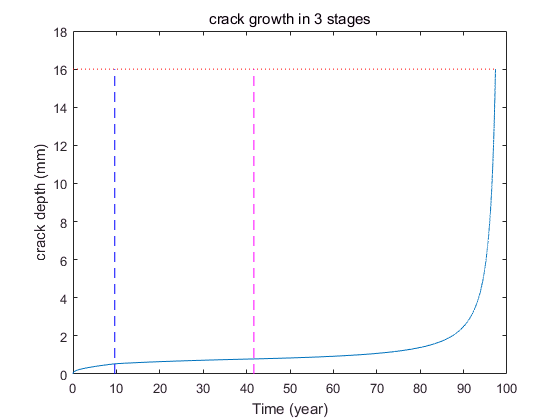


plot(t_his,a_his);
hold on;
plot([0,t_sum],[a_fail,a_fail],'r:');
plot([t_int,t_int],[0,a_fail],'b--');
plot([t_compe,t_compe],[0,a_fail],'m--');
xlabel("Time (year)"); ylabel("crack depth (mm)");
title('crack growth in 3 stages');
hold on;

fprintf(['CF Life: Stage 1 (%6.2f) + Stage 2 (%6.2f) + Stage 3 (%6.2f) = %6.2f years in total\n' ...
    'Stage 1: Stage 2: Stage 3 = %6.1f:%6.1f:%6.1f\n'], t_int, t_compe-t_int, t_sum - t_compe, t_sum, ...
    t_int/t_sum*100,(t_compe-t_int)/t_sum*100, (t_sum-t_compe)/t_sum*100);  % Result of corrosion fatigue life

CF Life: Stage 1 (  9.63) + Stage 2 ( 32.04) + Stage 3 ( 55.68) =  97.35 years in total
Stage 1: Stage 2: Stage 3 =    9.9:  32.9:  57.2
